# Challenge One - Basic algorithms

Assume a *directed acyclic graph* (DAG) in which nodes can have multiple parents and there is a single unique root node. The minimum number of edges connecting any node $n$ with the DAG's root node $r$ is considered the depth $d\left(n\right)$ of node $n$ . Because a node can have many parents, there might be several routes, of varying number of edges, from the node to the root r . Provide a test (see *Test Driven Development*) that executes your solution and verifies, it works as expected. Then write the function that returns the depth of a node given the DAG and test it with your test. Assume the DAG, i.e. the input to your function, to be represented as an *adjacency matrix* . Another input argument is the root node, i.e. consider the root node to be known so that your algorithm does not need to find it. Use any programming language you like to solve this challenge. You will receive extra points if you implement the solution in either Brainfuck or Assembler , but because you will be considered not totally sane we will not invite you to dinner. 

## Research

### Directed Acyclic Graph (DAG)

A graph $G$ is a finite nonempty set of objects, called vertices, together with a set of unordered pairs of distinct vertices, called edges. The set of vertices of a graph $G$ is called the vertex set of G, denoted by $V\left(G\right)$, and the set of edges is called the edge set of $G$, denoted by $E\left(G\right)$. The edge $e=\left\lbrace u,v\right\rbrace$ (or $e=\textrm{uv}$) is said to join the vertices $u$ and $v$. 

If $e=\textrm{uv}$ is an edge of $G$, then $u$ and $v$ are adjacent vertices, while $u$ and $e$ are incident, as are $v$ and $e$. Furthermore, if $e_1$ and $e_2$ are distinct edges of $G$ incident with a common vertex, then $e_1$ and $e_2$ are adjacent edges. It is convenient henceforth to denote an edge by $\textrm{uv}$ or $\textrm{vu}$ rather than by $\left\lbrace u,v\right\rbrace$. The cardinality of the vertex set of a graph $G$ is called the order of $G$ and is denoted by $n\left(G\right)$, or more simply by $n$ when the graph under consideration is clear, while the cardinality of its edge set is the size of $G$, denoted by $m\left(G\right)$ or $m$. An $\left(m,n\right)$ graph has order $n$ and size $m$. The graph of order $n=1$ is called the trivial graph. A nontrivial graph has at least two vertices.

### Adjacency Matrix


$$\textrm{tr}\left(A\right)=0$$


### Test Drive Development (TDD)

### Bellman Ford Algorithm

### Brainfuck

++++++++++[>+>+++>+++++++>++++++++++<<<<-]>>>+++.<++.>>+++++++++++++++++++.--------.++++++.---------.--------.<<.>>++++++++++++++.-----------------.+++++++++++++++++++.------------.---.+++++++++++++.<<.>>-----------.++++++++.<<.>>+++++.-----.<<.>>-----------.+++++.+++++..---------.+++++++++++++.<<++++++++++++.------------.>>--.----.-------.----.++++++++++++++++++.--------------.<<+.

## Intialize Graph

Please input the value $r$. In this instance, $r$ is the number of nodes and the index of the root node.

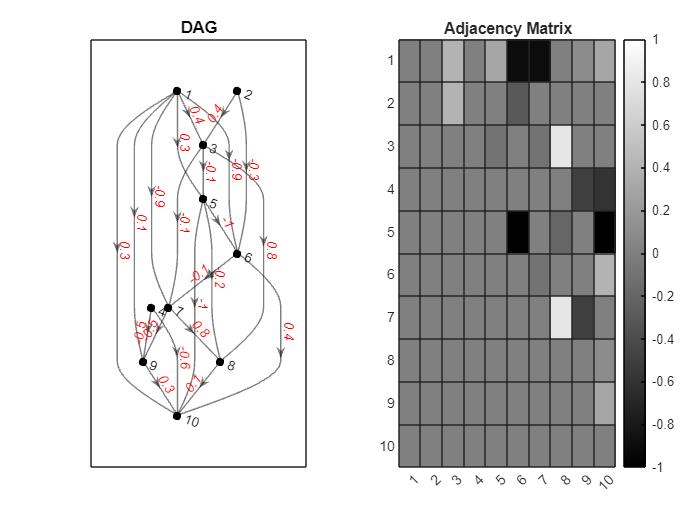

clf;
r=10; % Alle Wege fuehren nach Rom
weightedEdges = true; % Aber manche Wege sind einfach besser
[A,G]=generateRandomMatrix(r, weightedEdges);
dagPlotter(G,A,weightedEdges);

### Bellman-Ford Algorithm

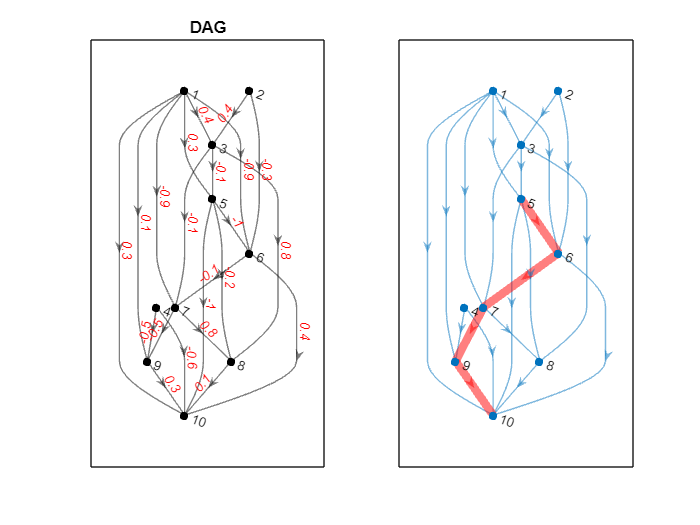

n = 5; % Choose your source;
E = table2array(G.Edges);
[d,allIterations, totalCost, path] = bellmanFord(n,G,E,r);

d

d = 1×10 table
    Node 1    Node 2    Node 3    Node 4    Node 5    Node 6    Node 7    Node 8    Node 9    Node 10
    ______    ______    ______    ______    ______    ______    ______    ______    ______    _______

     Inf       Inf       Inf       Inf        0         -1       -1.1      -0.3      -1.6      -1.3  


path

path =     10     9     7     6     5


allIterations

allIterations = 198×10 table
    Node 1    Node 2    Node 3    Node 4    Node 5    Node 6    Node 7    Node 8    Node 9    Node 10
    ______    ______    ______    ______    ______    ______    ______    ______    ______    _______

     Inf       Inf       Inf       Inf        0        Inf       Inf        Inf      Inf        Inf  
     Inf       Inf       Inf       Inf        0        Inf       Inf        Inf      Inf        Inf  
     Inf       Inf       Inf       Inf        0        Inf       Inf        Inf      Inf        Inf  
     Inf       Inf       Inf       Inf        0        Inf       Inf        Inf      Inf        Inf  
     Inf       Inf

totalCost

totalCost = -1.3000